% Expand Fourier series of periodic functions f(x) with period T, 
% given on the indicated intervals:
% f(x)=|x|; T=2; [-1;1]

clear
syms x real;
f(x)=abs(x);
L=1;

syms m integer;
[a0,a(m),b(m),abf(m)]=fourierseriesL(f,L)

$$a0 = 1$$

$$a(m) = \frac{2\,{\left(-1\right)}^{m}-2}{m^{2}\,\pi^{2}}$$

$$b(m) = 0$$

$$abf(m) = \frac{\cos\left(\pi \,m\,x\right)\,\left(2\,{\left(-1\right)}^{m}-2\right)}{m^{2}\,\pi^{2}}$$

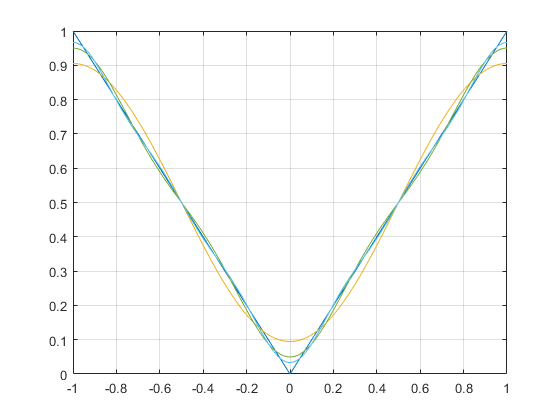


fplot(f(x),[-1 1]);
hold on;

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[-1 1])
    grid on
end
hold off

f1

$$f1 = \frac{1}{2}-\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}-\frac{4\,\cos\left(5\,\pi \,x\right)}{25\,\pi^{2}}-\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}$$

% 1/2 - (4*cos(3*pi*x))/(9*pi^2) - (4*cos(5*pi*x))/(25*pi^2) - (4*cos(pi*x))/pi^2

a0/2

$$ans = \frac{1}{2}$$

% 1/2
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & -\frac{4}{\pi^{2}} & 0 & -\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}\\ 2 & 0 & 0 & 0\\ 3 & -\frac{4}{9\,\pi^{2}} & 0 & -\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}\\ 4 & 0 & 0 & 0\\ 5 & -\frac{4}{25\,\pi^{2}} & 0 & -\frac{4\,\cos\left(5\,\pi \,x\right)}{25\,\pi^{2}} \end{array}\right)$$

% [ 1,      -4/pi^2, 0,        -(4*cos(pi*x))/pi^2]
% [ 2,            0, 0,                          0]
% [ 3,  -4/(9*pi^2), 0,  -(4*cos(3*pi*x))/(9*pi^2)]
% [ 4,            0, 0,                          0]
% [ 5, -4/(25*pi^2), 0, -(4*cos(5*pi*x))/(25*pi^2)]

syms m k pi;
abf2(k)=subs(abf(m),m,2*k-1)

$$abf2(k) = \frac{\cos\left(\pi \,x\,\left(2\,k-1\right)\right)\,\left(2\,{\left(-1\right)}^{2\,k-1}-2\right)}{\pi^{2}\,{\left(2\,k-1\right)}^{2}}$$

% (cos(x*pi*(2*k - 1))*(2*(-1)^(2*k - 1) - 2))/(pi^2*(2*k - 1)^2)
%                       =-2
abf2(k)=-4*cos(x*pi*(2*k - 1))/(pi^2*(2*k - 1)^2)

$$abf2(k) = -\frac{4\,\cos\left(\pi \,x\,\left(2\,k-1\right)\right)}{\pi^{2}\,{\left(2\,k-1\right)}^{2}}$$


for k=1:3
    k3(k)=k;
    abf3(k)=abf2(k);
end
ft2=[k3;abf3];
ft2'

$$ans = \left(\begin{array}{cc} 1 & -\frac{4\,\cos\left(\pi \,x\right)}{\pi^{2}}\\ 2 & -\frac{4\,\cos\left(3\,\pi \,x\right)}{9\,\pi^{2}}\\ 3 & -\frac{4\,\cos\left(5\,\pi \,x\right)}{25\,\pi^{2}} \end{array}\right)$$

% [ 1,        -(4*cos(pi*x))/pi^2]
% [ 2,  -(4*cos(3*pi*x))/(9*pi^2)]
% [ 3, -(4*cos(5*pi*x))/(25*pi^2)]